# **Modern Control Project : simulation of Transfer Function**

## **S.Mehdi Moosaviun**

## **ID:99413136**

**---------------------------------------------------------------------------------------------------------------------------------------**

**Question-1 : **Calculate the zeros and poles of the system (using MATLAB software)? Is the open loop system stable 

Is? Is the system minimum phase?

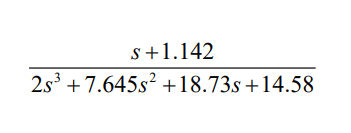

% Q_1 : Part A
numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];


sys = tf(numerator_coeffs, denominator_coeffs)

sys =
 
              3 s + 1.677
  -----------------------------------
  2 s^3 + 8.341 s^2 + 21.55 s + 16.61
 
Continuous-time transfer function.




zeros = zero(sys);
poles = pole(sys);


disp('Zeros:');

Zeros:


disp(zeros);

   -0.5590



disp('Poles:');

Poles:


disp(poles);

  -1.5191 + 2.2421i
  -1.5191 - 2.2421i
  -1.1323 + 0.0000i



% --------------------------
% Q_1 : Part B

is_stable = all(real(poles) < 0);

is_minimum_phase = all(real(zeros) < 0);

if is_stable
    disp('System is a stable Open loop system');
else
    disp('System is Not a stable Open loop system');
end

System is a stable Open loop system



if is_minimum_phase
    disp('System is a minimum phase system');
else
    disp('System is Not a minimum phase system ');
end

System is a minimum phase system


**Question-2** :  Calculate a state space view for the system?

% Convert the transfer function to state-space representation
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

disp('State-Space Representation:')

State-Space Representation:


disp('A matrix:')

A matrix:


disp(A)

   -4.1705  -10.7750   -8.3050
    1.0000         0         0
         0    1.0000         0



disp('B matrix:')

B matrix:


disp(B)

     1
     0
     0



disp('C matrix:')

C matrix:


disp(C)

         0    1.5000    0.8385



disp('D matrix:')

D matrix:


disp(D)

     0



**Question-3** :  Check the controllability and visibility of the resulting state space? Is it possible to design feedback? Is there a mode and mode viewer for this show? If the resulting state space display is uncontrollable It is to separate it into controllable and uncontrollable subsystems. Also, if the display of space mode It is invisible, and it is divided into observable and invisible subsystems. 

% Compute controllability matrix and its rank
controllability_matrix = ctrb(A, B);
rank_controllability = rank(controllability_matrix);

disp('Controllability Matrix:')

Controllability Matrix:


disp(controllability_matrix)

    1.0000   -4.1705    6.6181
         0    1.0000   -4.1705
         0         0    1.0000



disp('Rank of Controllability Matrix:')

Rank of Controllability Matrix:


disp(rank_controllability)

     3




% Compute observability matrix and its rank
observability_matrix = obsv(A, C);
rank_observability = rank(observability_matrix);

disp('Observability Matrix:')

Observability Matrix:


disp(observability_matrix)

         0    1.5000    0.8385
    1.5000    0.8385         0
   -5.4172  -16.1625  -12.4575



disp('Rank of Observability Matrix:')

Rank of Observability Matrix:


disp(rank_observability)

     3




% Check if the system is controllable
if rank_controllability == size(A, 1)
    disp('The system is controllable.')
else
    disp('The system is not controllable.')
end

The system is controllable.



% Check if the system is observable
if rank_observability == size(A, 1)
    disp('The system is observable.')
else
    disp('The system is not observable.')
end

The system is observable.


**Question-4** :  If the state space representation obtained in the previous part is not minimal, a state space representation Get a minimum for the system?

% Check if the system is minimal
if rank_controllability && rank_observability
    disp('The system is minimal.')
else
    disp('The system is not minimal.')
end

The system is minimal.


    
    sys_minimal = minreal(sys);
    [Am, Bm, Cm, Dm] = ssdata(sys_minimal);
    
    disp('Minimal State-Space Representation:')

Minimal State-Space Representation:


    disp('A matrix:')

A matrix:


    disp(Am)

   -4.1705   -2.6938   -1.0381
    4.0000         0         0
         0    2.0000         0



    disp('B matrix:')

B matrix:


    disp(Bm)

    0.5000
         0
         0



    disp('C matrix:')

C matrix:


    disp(Cm)

         0    0.7500    0.2096



    disp('D matrix:')

D matrix:


    disp(Dm)

     0



**Question-5** : Draw the system's open-loop response (if stable) per single step input and desired initial conditions.

% Check stability
is_stable = all(real(poles) < 0);
if is_stable
    disp('System is a stable Open loop system');
else
    disp('System is Not a stable Open loop system');
    return;
end

System is a stable Open loop system


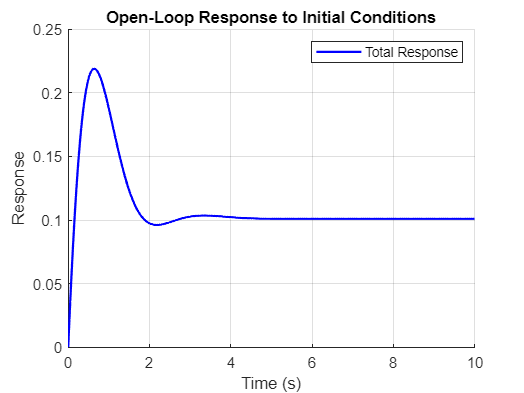


% % step(sys)

x0 = [0.5; 0; 0];

t = 0:0.01:10;

% Create state-space system
sys_ss = ss(A, B, C, D);

% Compute the response to the unit step input
[y_step, t, x_step] = step(sys_ss, t);

% Compute the zero-input response
[y_initial, t, x_initial] = initial(sys_ss, x0, t);

% Compute the total response 
total_response = y_step + y_initial;

figure;
hold on;
plot(t, total_response, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Response');
title('Open-Loop Response to Initial Conditions');
legend('Total Response');
grid on;
hold off;

**Question-6** :  Simulate the open loop system based on the representation of the obtained state space using the feedback of the negative unit in the form of a closed loop, plot the step response of the closed loop system, and get its poles and zeros?

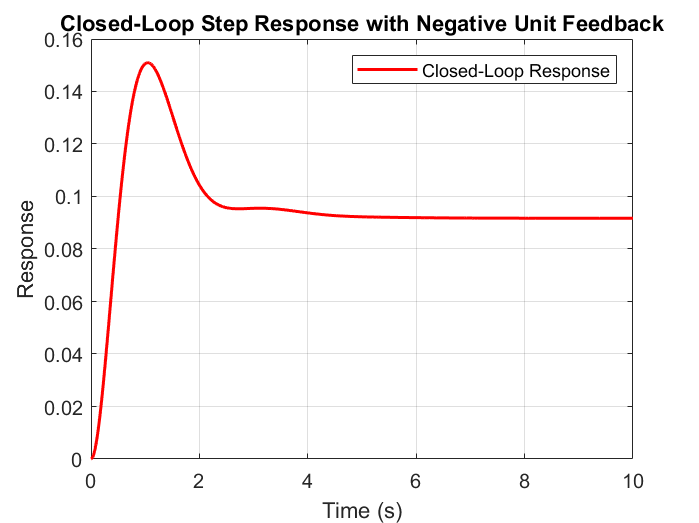

% Create the closed-loop system using negative unit feedback
sys_cl = feedback(sys_ss, 1);

% Compute the step response of the closed-loop system
[y_cl, t_cl] = step(sys_cl, t);

figure;
plot(t_cl, y_cl, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Response');
title('Closed-Loop Step Response with Negative Unit Feedback');
legend('Closed-Loop Response');
grid on;


% Compute zeros and poles of the closed-loop system
zeros_cl = zero(sys_cl);
poles_cl = pole(sys_cl);

disp('Closed-Loop Zeros:');

Closed-Loop Zeros:


disp(zeros_cl);

   -0.5590



disp('Closed-Loop Poles:');

Closed-Loop Poles:


disp(poles_cl);

  -1.5824 + 2.5668i
  -1.5824 - 2.5668i
  -1.0056 + 0.0000i



**Question - 7** :  To display the resulting state space for the system, design the state feedback so that the poles of the closed-loop system are positioned in the desired locations on the left side of the JΩ axis. Draw the stepping response of the closed-loop system and its control signal state variables. Compare the poles and zeros of the closed-loop and open-loop system. 

NOTE: Do this step to locate the far and near poles and control signal and feedback gain 

Compare the state obtained in both states with each other.

tspan = 0:0.01:10;

% Desired pole locations for far poles
P_far = [-5 -7 -10];
K_far = acker(A, B, P_far)

K_far =    17.8295  144.2250  341.6950



% Desired pole locations for near poles
P_near = [-1 -2 -3];
K_near = acker(A, B, P_near)

K_near =     1.8295    0.2250   -2.3050



% Simulate the system for far poles
[t_far, x_far] = ode45(@(t, x) d_Q7(t, x, A, B, K_far), tspan, x0);
u_far = -K_far * x_far';

% Simulate the system for near poles
[t_near, x_near] = ode45(@(t, x) d_Q7(t, x, A, B, K_near), tspan, x0);
u_near = -K_near * x_near';

% Open loop poles
openLoop_poles = eig(A);

% Closed loop poles for far poles
closedLoop_poles_far = eig(A - B * K_far);

% Closed loop poles for near poles
closedLoop_poles_near = eig(A - B * K_near);

disp('Open-Loop Poles:');

Open-Loop Poles:


disp(openLoop_poles);

  -1.5191 + 2.2421i
  -1.5191 - 2.2421i
  -1.1323 + 0.0000i



disp('Closed-Loop Poles (Far):');

Closed-Loop Poles (Far):


disp(closedLoop_poles_far);

  -10.0000
   -7.0000
   -5.0000



disp('Closed-Loop Poles (Near):');

Closed-Loop Poles (Near):


disp(closedLoop_poles_near);

   -3.0000
   -2.0000
   -1.0000



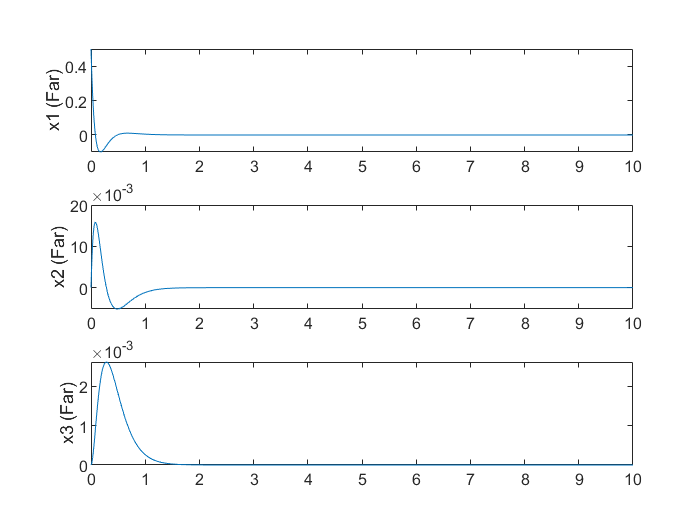


figure();
subplot(3, 1, 1);
plot(t_far, x_far(:, 1));
ylabel('x1 (Far)');
subplot(3, 1, 2);
plot(t_far, x_far(:, 2));
ylabel('x2 (Far)');
subplot(3, 1, 3);
plot(t_far, x_far(:, 3));
ylabel('x3 (Far)');

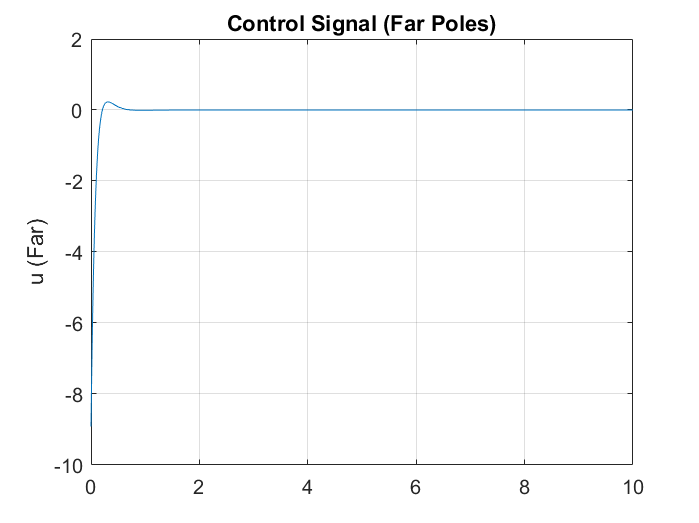


figure();
plot(t_far, u_far);
ylabel('u (Far)');
title('Control Signal (Far Poles)');
grid on

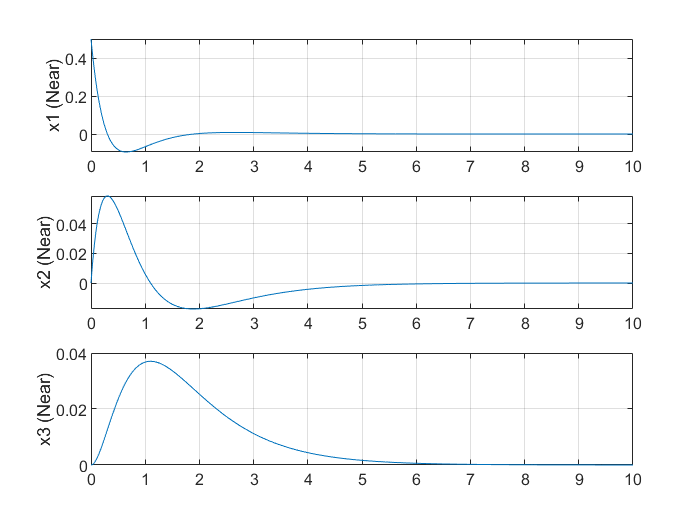


figure();
subplot(3, 1, 1);
plot(t_near, x_near(:, 1));
ylabel('x1 (Near)');
subplot(3, 1, 2);
plot(t_near, x_near(:, 2));
ylabel('x2 (Near)');
subplot(3, 1, 3);
plot(t_near, x_near(:, 3));
ylabel('x3 (Near)');

subplot(3,1,1)
grid on
subplot(3,1,2)
grid on
subplot(3,1,3)
grid on

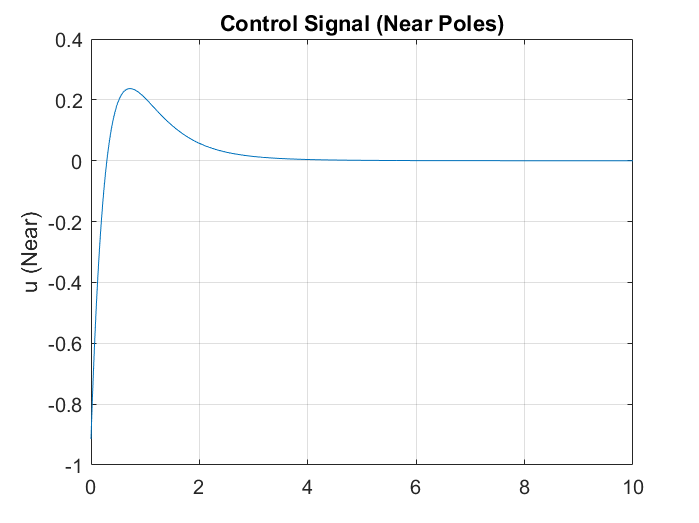


figure();
plot(t_near, u_near);
ylabel('u (Near)');
title('Control Signal (Near Poles)');
grid on


% Closed-loop system for far poles
closeLoop_far = ss(A - B * K_far, B, C, D);
[y_s_far, t_s_far, x_s_far] = step(closeLoop_far, tspan);
[y_i_far, t_i_far, x_i_far] = initial(closeLoop_far, x0, tspan);
y_far = y_s_far + y_i_far;
stepinfo(closeLoop_far)

ans = struct with fields:
         RiseTime: 0.0492
    TransientTime: 1.3704
     SettlingTime: 1.5707
      SettlingMin: 0.0024
      SettlingMax: 0.0087
        Overshoot: 261.5084
       Undershoot: 0
             Peak: 0.0087
         PeakTime: 0.3132


% Closed-loop system for near poles
closeLoop_near = ss(A - B * K_near, B, C, D);
[y_s_near, t_s_near, x_s_near] = step(closeLoop_near, tspan);
[y_i_near, t_i_near, x_i_near] = initial(closeLoop_near, x0, tspan);
y_near = y_s_near + y_i_near;
stepinfo(closeLoop_near)

ans = struct with fields:
         RiseTime: 0.6452
    TransientTime: 4.7450
     SettlingTime: 4.7450
      SettlingMin: 0.1290
      SettlingMax: 0.1678
        Overshoot: 20.0904
       Undershoot: 0
             Peak: 0.1678
         PeakTime: 1.7193


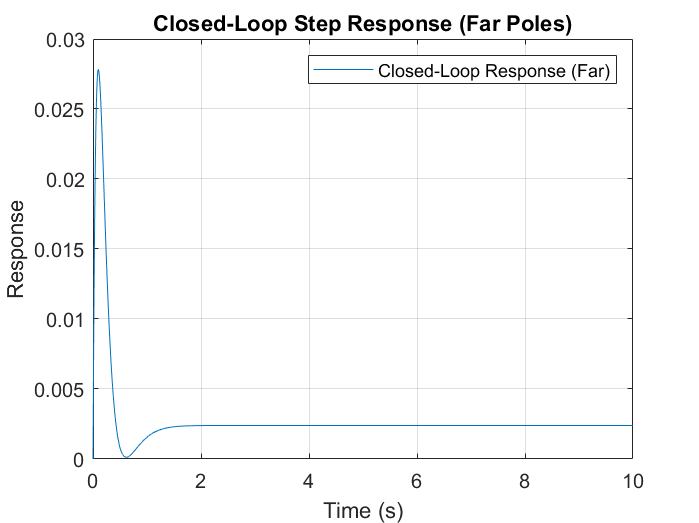

figure;
plot(t_s_far, y_far);
xlabel('Time (s)');
ylabel('Response');
title('Closed-Loop Step Response (Far Poles)');
legend('Closed-Loop Response (Far)');

xlim([0.00 10.00])
ylim([0.0000 0.0300])
grid on

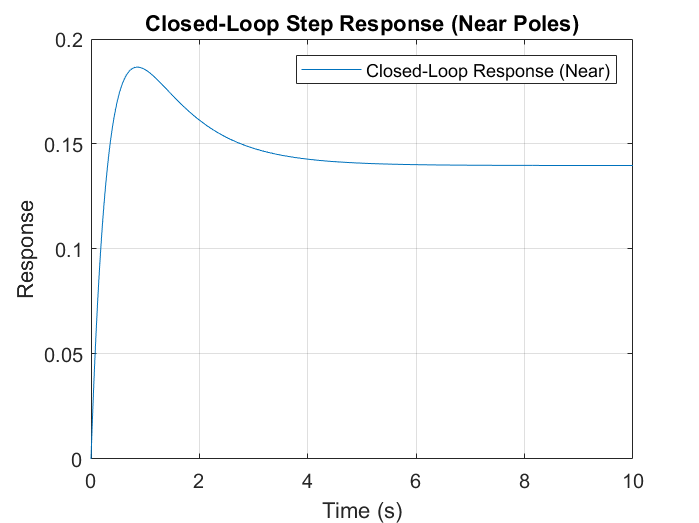


figure;
plot(t_s_near, y_near);
xlabel('Time (s)');
ylabel('Response');
title('Closed-Loop Step Response (Near Poles)');
legend('Closed-Loop Response (Near)');

xlim([0.00 10.00])
ylim([0.000 0.200])
grid on

**Question-8** :  Design a static tracker to show the space of the obtained state. 

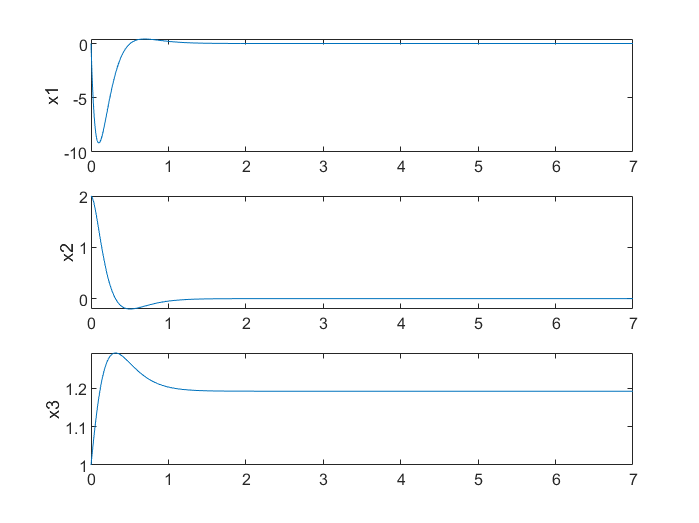

% Desired pole locations
P = [-5 -7 -10];
K = acker(A, B, P);

% Define initial conditions
x0 = [0; 2; 1];

tspan = 0:0.01:7;

% Compute the gain for the static tracker
syms s;
Ga = C * inv(s * eye(size(A)) - (A - B * K)) * B;
p = inv(-C * inv(A - B * K) * B); % for s=0
r = 1; 

% Simulate the system
[t, x] = ode45(@(t, x) d_Q8(t, x, A, B, C, K, p, r), tspan, x0);

% Compute the control signal and output
u = -K * x' + p * r;
y = C * x';

% Plot state variables
figure;
subplot(3, 1, 1);
plot(t, x(:, 1));
ylabel('x1');
subplot(3, 1, 2);
plot(t, x(:, 2));
ylabel('x2');
subplot(3, 1, 3);
plot(t, x(:, 3));
ylabel('x3');

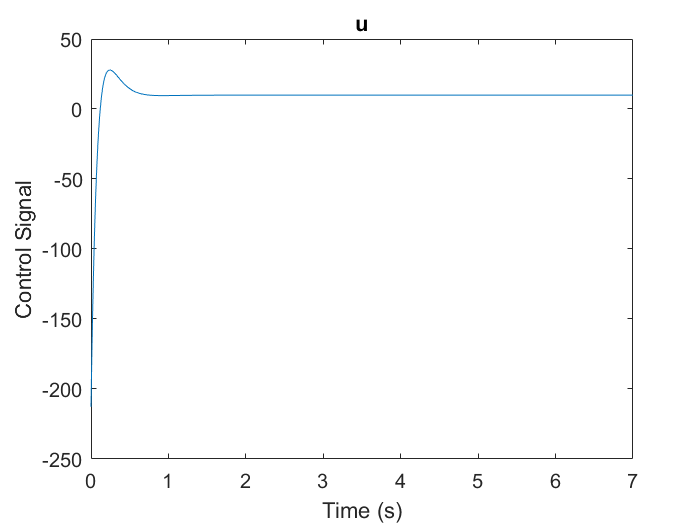


figure;
plot(t, u);
title('u');
ylabel('Control Signal');
xlabel('Time (s)');

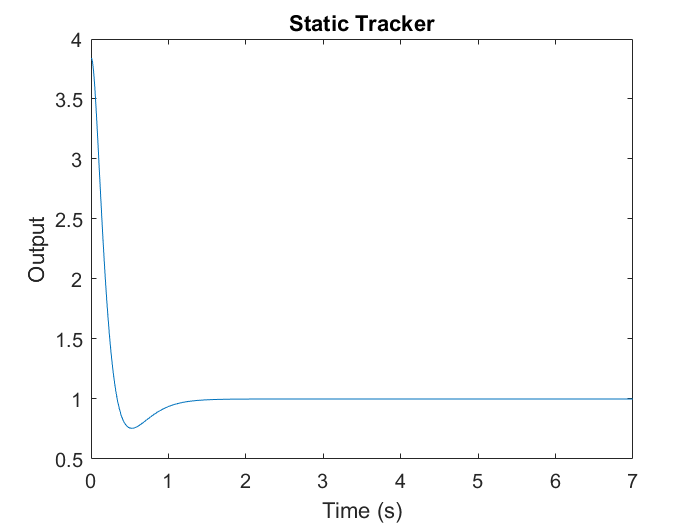


figure;
plot(t, y);
title('Static Tracker');
ylabel('Output');
xlabel('Time (s)');

**Question-9** : Design an integral detector to show the space of the obtained state. 

clear all
clc
% Define the coefficients of the numerator and denominator of the transfer function
numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];

% Create the transfer function
sys = tf(numerator_coeffs, denominator_coeffs);

% Convert the transfer function to state-space representation
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

% Check if the system is controllable
n = size(A, 1); % number of states
m = size(C, 1); % number of outputs

if rank(ctrb(A, B)) == n
    disp('System is controllable')
else
    disp('System is not controllable')
    return;
end

System is controllable



% Check if the augmented matrix is full rank
Abar = [A zeros(n, m); -C zeros(m, m)];
Bbar = [B; zeros(m, 1)];

if rank([B A; zeros(m, 1) -C]) == (n + m)
    disp('System is integrally controllable')
else
    disp('System is not integrally controllable')
    return;
end

System is integrally controllable


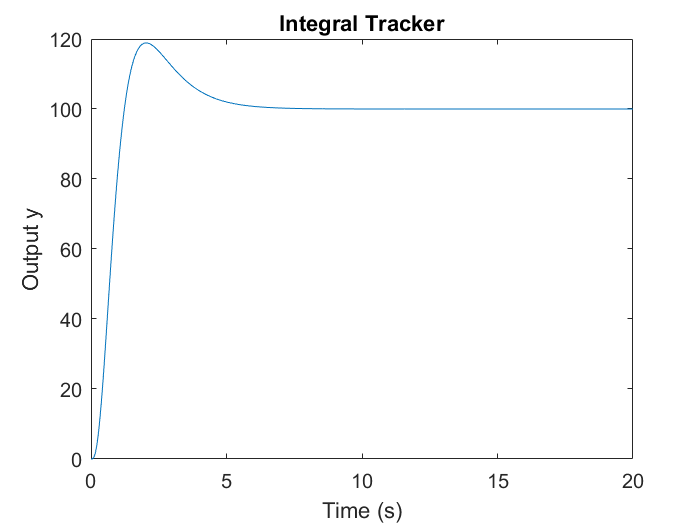


% Desired pole locations for the augmented system
P = [-1 -2 -3 -4];

% Calculate the feedback gain for the augmented system
K = acker(Abar, Bbar, P);
K1 = K(1:n);
K2 = K(n+1:n+m);

% Initial state
x = [0; 0; 0; 0];

% Time vector
t = 0:0.01:20;
[rt, ct] = size(t);

% Desired output
yd = 1;

% Disturbance
w = zeros(n, 1);

% Simulate the system
x_traj = zeros(n+m, ct);
u_traj = zeros(1, ct);
y_traj = zeros(m, ct);

for k = 2:ct
    u_traj(k) = [-K1 -K2] * x;
    x = x + 0.01 * (Abar * x + Bbar * u_traj(k)) + [zeros(n, 1); ones(m, 1)] * yd + [w; zeros(m, 1)];
    x_traj(:, k) = x;
end

% Output
y_traj = C * x_traj(1:n, :);

figure;
plot(t, y_traj);
title('Integral Tracker');
xlabel('Time (s)');
ylabel('Output y');

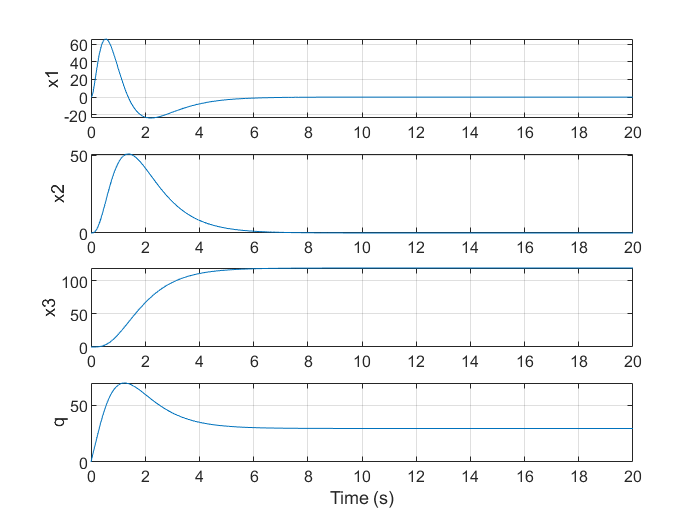


x1 = x_traj(1, :);
x2 = x_traj(2, :);
x3 = x_traj(3, :);
q = x_traj(4, :);

figure;
subplot(4, 1, 1);
plot(t, x1);
ylabel('x1');
grid on;

subplot(4, 1, 2);
plot(t, x2);
ylabel('x2');
grid on;

subplot(4, 1, 3);
plot(t, x3);
ylabel('x3');
grid on;

subplot(4, 1, 4);
plot(t, q);
ylabel('q');
grid on;
xlabel('Time (s)');

**Question-10** : Compare the answers of the two detectors designed in questions 8 and 9 and analyze the result from the following perspectives.

 Tracking function

 Resistance in the presence of changing model parameters

 Closed-loop system operation by introducing constant disturbances

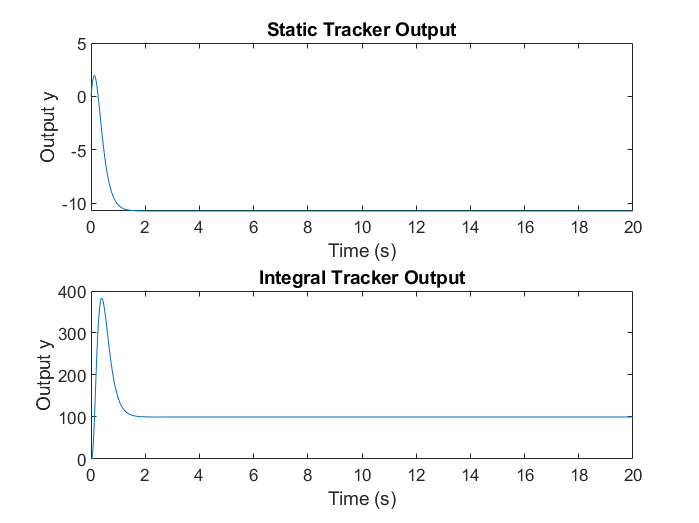

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];

% Create the transfer function
sys = tf(numerator_coeffs, denominator_coeffs);

% Convert the transfer function to state-space representation
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

% Check if the system is controllable
n = size(A, 1); % number of states
m = size(C, 1); % number of outputs

Abar = [A zeros(n, m); -C zeros(m, m)];
Bbar = [B; zeros(m, size(B, 2))];

% Desired pole locations for the static tracker
P_static = [-5 -7 -10];
K_static = acker(A, B, P_static);

% Desired pole locations for the integral tracker
P_integral = [-5 -7 -10 -12];
K_integral = acker(Abar, Bbar, P_integral);
K1 = K_integral(1:n);
K2 = K_integral(n+1:end);

% Initial state
x0 = [2; 0; 0];
x0_integral = [2; 0; 0; 0];

% Time vector
t = 0:0.01:20;
[rt, ct] = size(t);

% Desired output
yd = 1;

% Disturbance
w = [0.1; 0.1; 0.1]; % disturbance

% Simulate the static tracker
x_static = x0;
x_static_traj = zeros(n, ct);
u_static_traj = zeros(1, ct);
y_static_traj = zeros(m, ct);

for k = 2:ct
    u_static_traj(k) = -K_static * x_static;
    x_static = x_static + 0.01 * (A * x_static + B * u_static_traj(k)) + w;
    x_static_traj(:, k) = x_static;
end

y_static_traj = C * x_static_traj;

% Simulate the integral tracker
x_integral = x0_integral;
x_integral_traj = zeros(n + m, ct);
u_integral_traj = zeros(1, ct);
y_integral_traj = zeros(m, ct);

for k = 2:ct
    u_integral_traj(k) = [-K1 -K2] * x_integral;
    x_integral = x_integral + 0.01 * (Abar * x_integral + Bbar * u_integral_traj(k)) + [zeros(n, 1); ones(m, 1)] * yd + [w; zeros(m, 1)];
    x_integral_traj(:, k) = x_integral;
end

y_integral_traj = C * x_integral_traj(1:n, :);

figure;
subplot(2,1,1);
plot(t, y_static_traj);
title('Static Tracker Output');
xlabel('Time (s)');
ylabel('Output y');

subplot(2,1,2);
plot(t, y_integral_traj);
title('Integral Tracker Output');
xlabel('Time (s)');
ylabel('Output y');

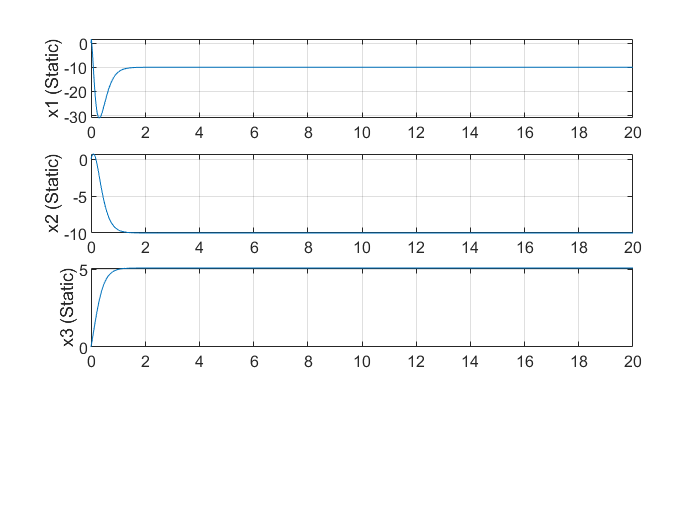


figure;
subplot(4, 1, 1);
plot(t, x_static_traj(1, :));
ylabel('x1 (Static)');
grid on;

subplot(4, 1, 2);
plot(t, x_static_traj(2, :));
ylabel('x2 (Static)');
grid on;

subplot(4, 1, 3);
plot(t, x_static_traj(3, :));
ylabel('x3 (Static)');
grid on;

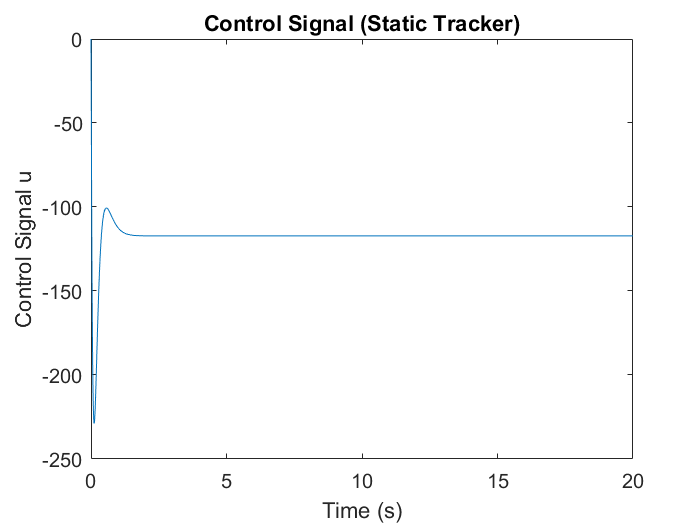


figure;
plot(t, u_static_traj);
title('Control Signal (Static Tracker)');
xlabel('Time (s)');
ylabel('Control Signal u');

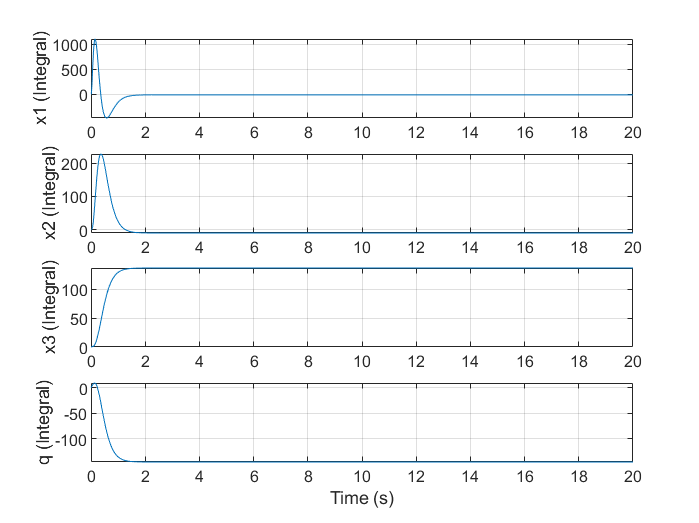


figure;
subplot(4, 1, 1);
plot(t, x_integral_traj(1, :));
ylabel('x1 (Integral)');
grid on;

subplot(4, 1, 2);
plot(t, x_integral_traj(2, :));
ylabel('x2 (Integral)');
grid on;

subplot(4, 1, 3);
plot(t, x_integral_traj(3, :));
ylabel('x3 (Integral)');
grid on;

subplot(4, 1, 4);
plot(t, x_integral_traj(4, :));
ylabel('q (Integral)');
grid on;
xlabel('Time (s)');

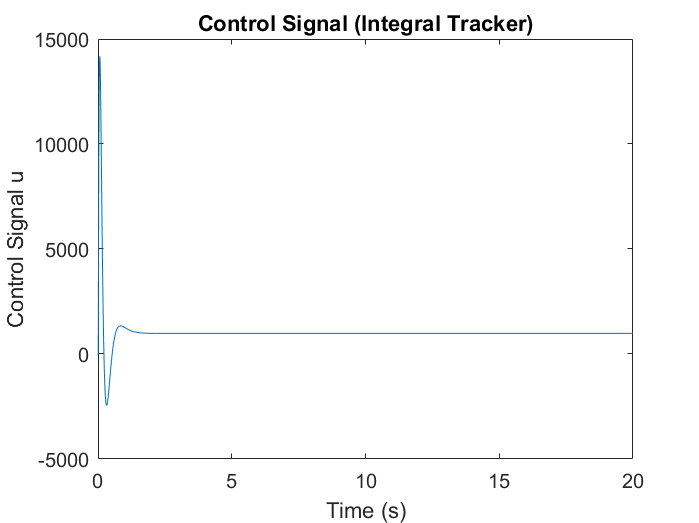


figure;
plot(t, u_integral_traj);
title('Control Signal (Integral Tracker)');
xlabel('Time (s)');
ylabel('Control Signal u');

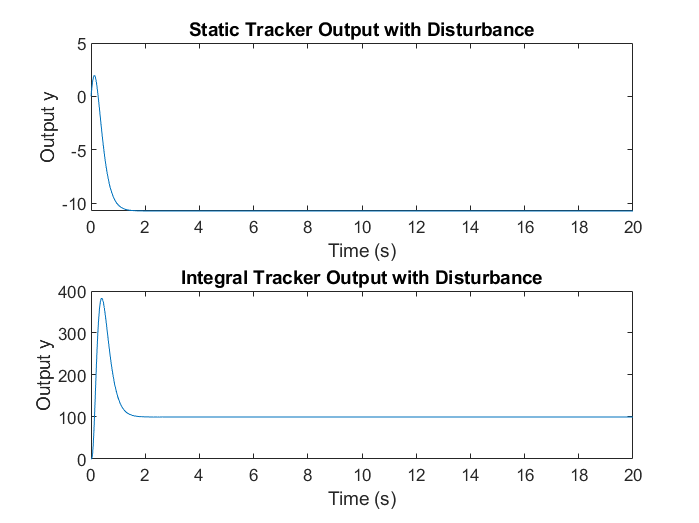


% Add disturbances and compare the responses
disturbance = [0.1; 0.1; 0.1]; % Example disturbance

% Simulate the static tracker with disturbance
x_static = x0;
x_static_traj_disturbance = zeros(n, ct);
for k = 2:ct
    u_static_traj(k) = -K_static * x_static;
    x_static = x_static + 0.01 * (A * x_static + B * u_static_traj(k)) + disturbance;
    x_static_traj_disturbance(:, k) = x_static;
end
y_static_traj_disturbance = C * x_static_traj_disturbance;

% Simulate the integral tracker with disturbance
x_integral = x0_integral;
x_integral_traj_disturbance = zeros(n + m, ct);
for k = 2:ct
    u_integral_traj(k) = [-K1 -K2] * x_integral;
    x_integral = x_integral + 0.01 * (Abar * x_integral + Bbar * u_integral_traj(k)) + [zeros(n, 1); ones(m, 1)] * yd + [disturbance; zeros(m, 1)];
    x_integral_traj_disturbance(:, k) = x_integral;
end
y_integral_traj_disturbance = C * x_integral_traj_disturbance(1:n, :);

figure;
subplot(2,1,1);
plot(t, y_static_traj_disturbance);
title('Static Tracker Output with Disturbance');
xlabel('Time (s)');
ylabel('Output y');

subplot(2,1,2);
plot(t, y_integral_traj_disturbance);
title('Integral Tracker Output with Disturbance');
xlabel('Time (s)');
ylabel('Output y');

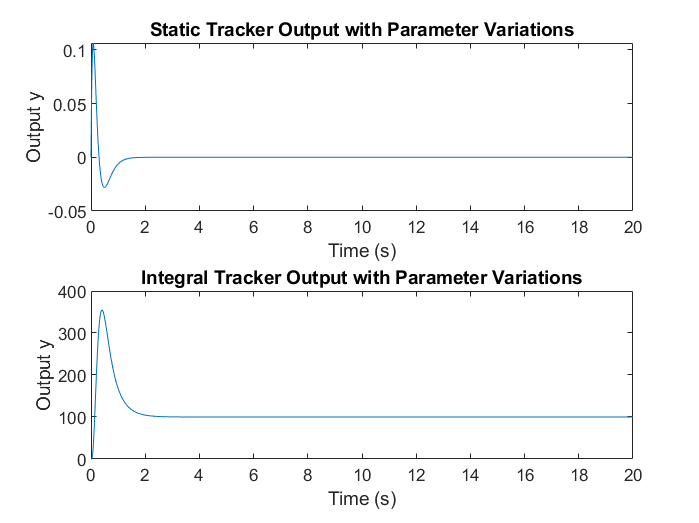


% Simulate the static tracker with parameter variations
A_variation = A + 0.1 * eye(size(A));
x_static = x0;
x_static_traj_variation = zeros(n, ct);
for k = 2:ct
    u_static_traj(k) = -K_static * x_static;
    x_static = x_static + 0.01 * (A_variation * x_static + B * u_static_traj(k));
    x_static_traj_variation(:, k) = x_static;
end
y_static_traj_variation = C * x_static_traj_variation;

% Simulate the integral tracker with parameter variations
x_integral = x0_integral;
x_integral_traj_variation = zeros(n + m, ct);
for k = 2:ct
    u_integral_traj(k) = [-K1 -K2] * x_integral;
    x_integral = x_integral + 0.01 * ([A_variation zeros(n, m); -C zeros(m, m)] * x_integral + Bbar * u_integral_traj(k)) + [zeros(n, 1); ones(m, 1)] * yd;
    x_integral_traj_variation(:, k) = x_integral;
end
y_integral_traj_variation = C * x_integral_traj_variation(1:n, :);

figure;
subplot(2,1,1);
plot(t, y_static_traj_variation);
title('Static Tracker Output with Parameter Variations');
xlabel('Time (s)');
ylabel('Output y');

subplot(2,1,2);
plot(t, y_integral_traj_variation);
title('Integral Tracker Output with Parameter Variations');
xlabel('Time (s)');
ylabel('Output y');

**Question-11** : To display the obtained state space for the given system, design a full-order observer. What is the criterion for selecting the poles that see the state? Plot system mode variables and estimation errors. In this question, choose two categories of slow and fast poles for the observer and design the corresponding full order observer. Plot and compare the responses of the system's original state variables and the state variables estimated by two full-order viewers. (Both cases).

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];

[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

% Desired pole locations for the observer
P_slow = [-1 -2 -3];  % Poles for slow observer
P_fast = [-10 -20 -30];  % Poles for fast observer

% Calculate the observer gain for slow poles
K_slow = acker(A', C', P_slow);
L_slow = K_slow';

% Calculate the observer gain for fast poles
K_fast = acker(A', C', P_fast);
L_fast = K_fast';

disp('Observer gain L (slow poles):');

Observer gain L (slow poles):


disp(L_slow);

   -5.5048
    1.0165
    0.3634




disp('Observer gain L (fast poles):');

Observer gain L (fast poles):


disp(L_fast);

   1.0e+03 *

    0.2202
    0.6273
   -1.0557



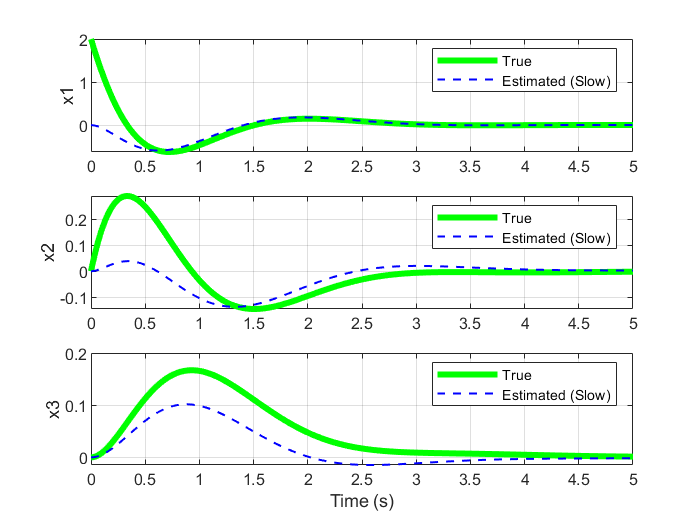


% Initial state and observer initial state
x0 = [2; 0; 0];
x0_est_slow = [0; 0; 0];
x0_est_fast = [0; 0; 0];

% Initial combined state for ODE solver
x0_combined_slow = [x0; x0_est_slow];
x0_combined_fast = [x0; x0_est_fast];

tspan = 0:0.01:5;

% Simulate the system with slow poles
[t_slow, x_slow] = ode45(@(t, x) observer_dynamics(t, x, A, B, C, L_slow), tspan, x0_combined_slow);

% Simulate the system with fast poles
[t_fast, x_fast] = ode45(@(t, x) observer_dynamics(t, x, A, B, C, L_fast), tspan, x0_combined_fast);

% Extract true states and estimated states for slow poles
x_true_slow = x_slow(:, 1:3);
x_est_slow = x_slow(:, 4:6);

% Extract true states and estimated states for fast poles
x_true_fast = x_fast(:, 1:3);
x_est_fast = x_fast(:, 4:6);

% Calculate estimation error for slow poles
error_slow = x_true_slow - x_est_slow;

% Calculate estimation error for fast poles
error_fast = x_true_fast - x_est_fast;

figure;
subplot(3,1,1);
plot(t_slow, x_true_slow(:, 1), 'g', 'linewidth', 3);
hold on;
plot(t_slow, x_est_slow(:, 1), 'b--', 'linewidth', 1);
ylabel('x1');
legend('True', 'Estimated (Slow)');
grid on;

subplot(3,1,2);
plot(t_slow, x_true_slow(:, 2), 'g', 'linewidth', 3);
hold on;
plot(t_slow, x_est_slow(:, 2), 'b--', 'linewidth', 1);
ylabel('x2');
legend('True', 'Estimated (Slow)');
grid on;

subplot(3,1,3);
plot(t_slow, x_true_slow(:, 3), 'g', 'linewidth', 3);
hold on;
plot(t_slow, x_est_slow(:, 3), 'b--', 'linewidth', 1);
ylabel('x3');
legend('True', 'Estimated (Slow)');
xlabel('Time (s)');
grid on;

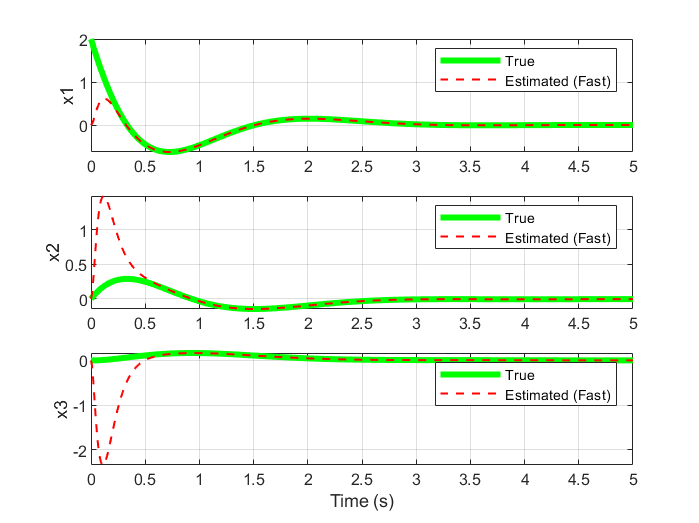


figure;
subplot(3,1,1);
plot(t_fast, x_true_fast(:, 1), 'g', 'linewidth', 3);
hold on;
plot(t_fast, x_est_fast(:, 1), 'r--', 'linewidth', 1);
ylabel('x1');
legend('True', 'Estimated (Fast)');
grid on;

subplot(3,1,2);
plot(t_fast, x_true_fast(:, 2), 'g', 'linewidth', 3);
hold on;
plot(t_fast, x_est_fast(:, 2), 'r--', 'linewidth', 1);
ylabel('x2');
legend('True', 'Estimated (Fast)');
grid on;

subplot(3,1,3);
plot(t_fast, x_true_fast(:, 3), 'g', 'linewidth', 3);
hold on;
plot(t_fast, x_est_fast(:, 3), 'r--', 'linewidth', 1);
ylabel('x3');
legend('True', 'Estimated (Fast)');
xlabel('Time (s)');
grid on;

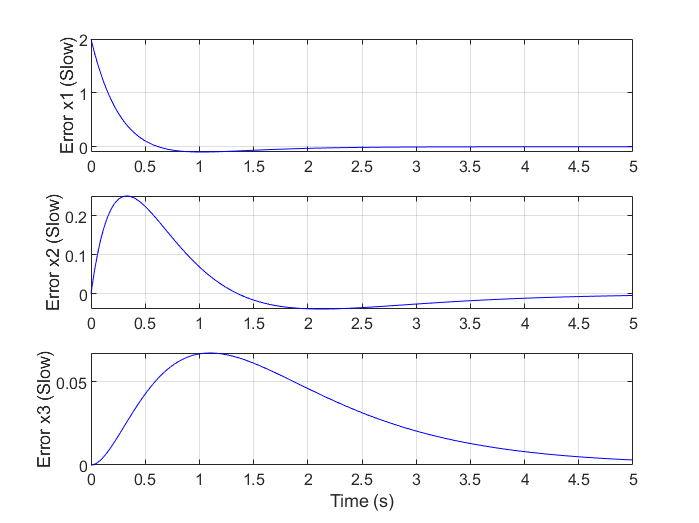


figure;
subplot(3,1,1);
plot(t_slow, error_slow(:, 1), 'b');
ylabel('Error x1 (Slow)');
grid on;

subplot(3,1,2);
plot(t_slow, error_slow(:, 2), 'b');
ylabel('Error x2 (Slow)');
grid on;

subplot(3,1,3);
plot(t_slow, error_slow(:, 3), 'b');
ylabel('Error x3 (Slow)');
xlabel('Time (s)');
grid on;

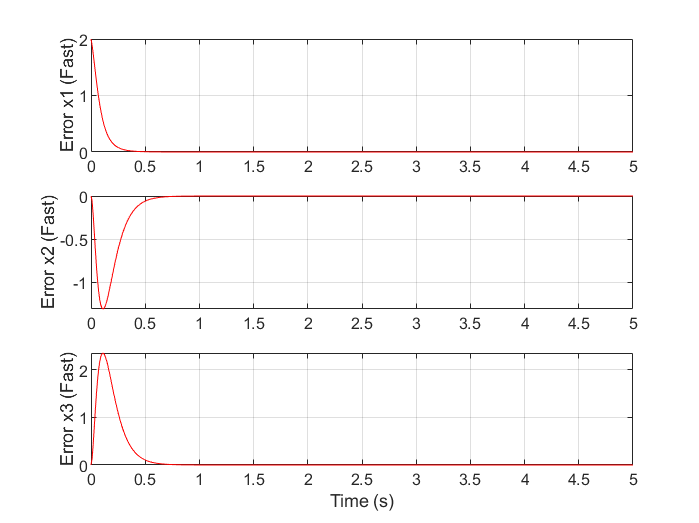


figure;
subplot(3,1,1);
plot(t_fast, error_fast(:, 1), 'r');
ylabel('Error x1 (Fast)');
grid on;

subplot(3,1,2);
plot(t_fast, error_fast(:, 2), 'r');
ylabel('Error x2 (Fast)');
grid on;

subplot(3,1,3);
plot(t_fast, error_fast(:, 3), 'r');
ylabel('Error x3 (Fast)');
xlabel('Time (s)');
grid on;

**Question-12** : Change one of the system parameters and use the same viewer as the previous step to estimate the changed system states. Analyze the result.

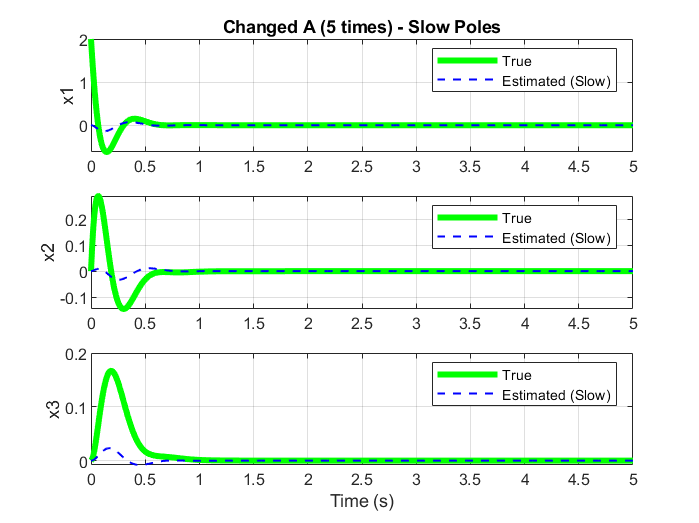

% Change A matrix (5 times) and simulate
A_changed = 5 * A;
[t_slow_A, x_slow_A] = ode45(@(t, x) observer_dynamics(t, x, A_changed, B, C, L_slow), tspan, x0_combined_slow);
[t_fast_A, x_fast_A] = ode45(@(t, x) observer_dynamics(t, x, A_changed, B, C, L_fast), tspan, x0_combined_fast);

x_true_slow_A = x_slow_A(:, 1:3);
x_est_slow_A = x_slow_A(:, 4:6);
x_true_fast_A = x_fast_A(:, 1:3);
x_est_fast_A = x_fast_A(:, 4:6);
error_slow_A = x_true_slow_A - x_est_slow_A;
error_fast_A = x_true_fast_A - x_est_fast_A;

% Plot true states and estimated states with changed A for slow poles
figure;
subplot(3,1,1);
plot(t_slow_A, x_true_slow_A(:, 1), 'g', 'linewidth', 3);
hold on;
plot(t_slow_A, x_est_slow_A(:, 1), 'b--', 'linewidth', 1);
ylabel('x1');
legend('True', 'Estimated (Slow)');
title('Changed A (5 times) - Slow Poles');
grid on;

subplot(3,1,2);
plot(t_slow_A, x_true_slow_A(:, 2), 'g', 'linewidth', 3);
hold on;
plot(t_slow_A, x_est_slow_A(:, 2), 'b--', 'linewidth', 1);
ylabel('x2');
legend('True', 'Estimated (Slow)');
grid on;

subplot(3,1,3);
plot(t_slow_A, x_true_slow_A(:, 3), 'g', 'linewidth', 3);
hold on;
plot(t_slow_A, x_est_slow_A(:, 3), 'b--', 'linewidth', 1);
ylabel('x3');
legend('True', 'Estimated (Slow)');
xlabel('Time (s)');
grid on;

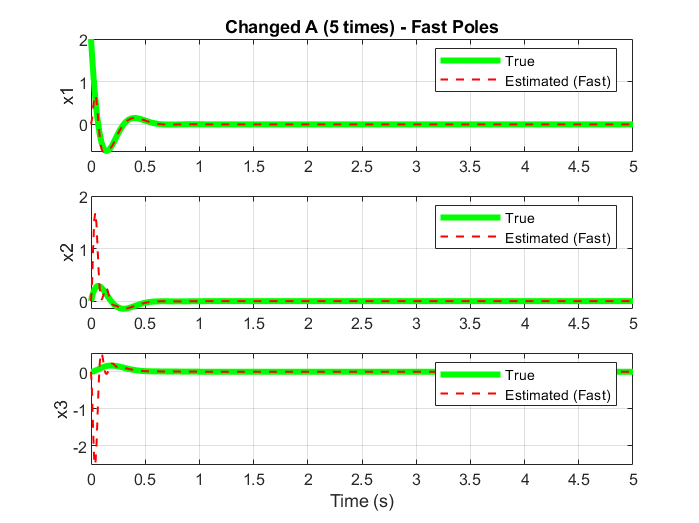


% Plot true states and estimated states with changed A for fast poles
figure;
subplot(3,1,1);
plot(t_fast_A, x_true_fast_A(:, 1), 'g', 'linewidth', 3);
hold on;
plot(t_fast_A, x_est_fast_A(:, 1), 'r--', 'linewidth', 1);
ylabel('x1');
legend('True', 'Estimated (Fast)');
title('Changed A (5 times) - Fast Poles');
grid on;

subplot(3,1,2);
plot(t_fast_A, x_true_fast_A(:, 2), 'g', 'linewidth', 3);
hold on;
plot(t_fast_A, x_est_fast_A(:, 2), 'r--', 'linewidth', 1);
ylabel('x2');
legend('True', 'Estimated (Fast)');
grid on;

subplot(3,1,3);
plot(t_fast_A, x_true_fast_A(:, 3), 'g', 'linewidth', 3);
hold on;
plot(t_fast_A, x_est_fast_A(:, 3), 'r--', 'linewidth', 1);
ylabel('x3');
legend('True', 'Estimated (Fast)');
xlabel('Time (s)');
grid on;

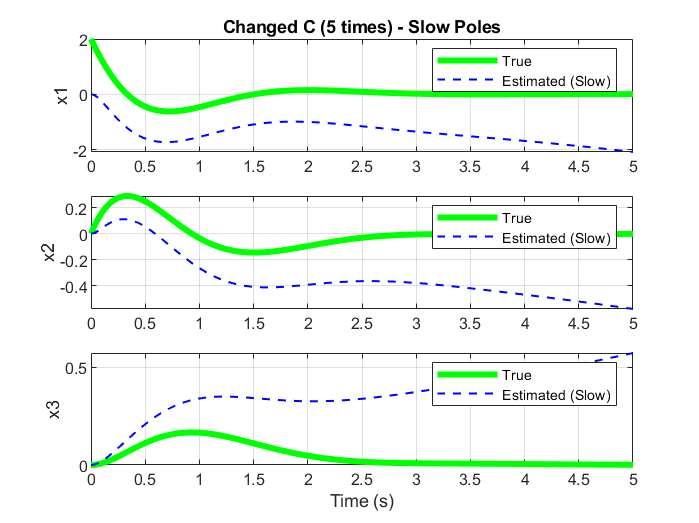


% Change C matrix (5 times) and simulate
C_changed = 5 * C;
[t_slow_C, x_slow_C] = ode45(@(t, x) observer_dynamics(t, x, A, B, C_changed, L_slow), tspan, x0_combined_slow);
[t_fast_C, x_fast_C] = ode45(@(t, x) observer_dynamics(t, x, A, B, C_changed, L_fast), tspan, x0_combined_fast);

x_true_slow_C = x_slow_C(:, 1:3);
x_est_slow_C = x_slow_C(:, 4:6);
x_true_fast_C = x_fast_C(:, 1:3);
x_est_fast_C = x_fast_C(:, 4:6);
error_slow_C = x_true_slow_C - x_est_slow_C;
error_fast_C = x_true_fast_C - x_est_fast_C;

% Plot true states and estimated states with changed C for slow poles
figure;
subplot(3,1,1);
plot(t_slow_C, x_true_slow_C(:, 1), 'g', 'linewidth', 3);
hold on;
plot(t_slow_C, x_est_slow_C(:, 1), 'b--', 'linewidth', 1);
ylabel('x1');
legend('True', 'Estimated (Slow)');
title('Changed C (5 times) - Slow Poles');
grid on;

subplot(3,1,2);
plot(t_slow_C, x_true_slow_C(:, 2), 'g', 'linewidth', 3);
hold on;
plot(t_slow_C, x_est_slow_C(:, 2), 'b--', 'linewidth', 1);
ylabel('x2');
legend('True', 'Estimated (Slow)');
grid on;

subplot(3,1,3);
plot(t_slow_C, x_true_slow_C(:, 3), 'g', 'linewidth', 3);
hold on;
plot(t_slow_C, x_est_slow_C(:, 3), 'b--', 'linewidth', 1);
ylabel('x3');
legend('True', 'Estimated (Slow)');
xlabel('Time (s)');
grid on;

disp('------------------------------------------------------------------------------------------------------------')

------------------------------------------------------------------------------------------------------------


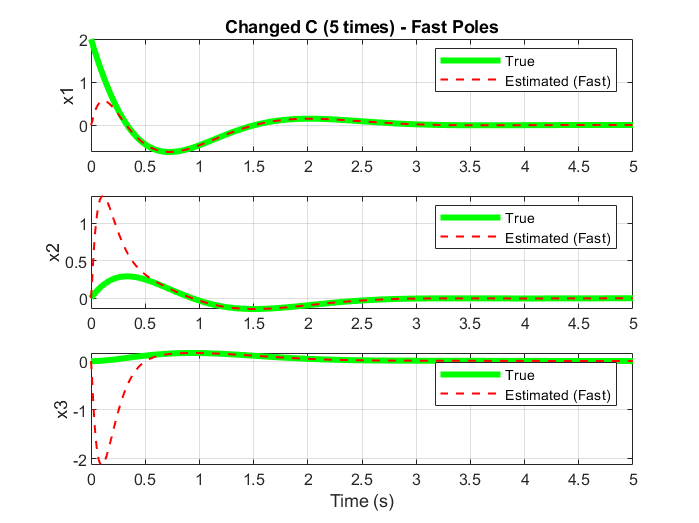


% Plot true states and estimated states with changed C for fast poles
figure;
subplot(3,1,1);
plot(t_fast_C, x_true_fast_C(:, 1), 'g', 'linewidth', 3);
hold on;
plot(t_fast_C, x_est_fast_C(:, 1), 'r--', 'linewidth', 1);
ylabel('x1');
legend('True', 'Estimated (Fast)');
title('Changed C (5 times) - Fast Poles');
grid on;

subplot(3,1,2);
plot(t_fast_C, x_true_fast_C(:, 2), 'g', 'linewidth', 3);
hold on;
plot(t_fast_C, x_est_fast_C(:, 2), 'r--', 'linewidth', 1);
ylabel('x2');
legend('True', 'Estimated (Fast)');
grid on;

subplot(3,1,3);
plot(t_fast_C, x_true_fast_C(:, 3), 'g', 'linewidth', 3);
hold on;
plot(t_fast_C, x_est_fast_C(:, 3), 'r--', 'linewidth', 1);
ylabel('x3');
legend('True', 'Estimated (Fast)');
xlabel('Time (s)');
grid on;

**Question-13** : To display the resulting state space for the system, design an order reduction viewer. Plot system mode variables and estimation errors.

clear all;
clc;

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

P = [C; 1 0 0; 0 1 0];

disp('Rank of P:');

Rank of P:


disp(rank(P));

     3




% Desired poles for the reduced-order observer
P_desire = [-30 -33];

% Transform the system
Abar = P * A / P;
Bbar = P * B;
Cbar = C / P;

% Partition the transformed system
A22 = Abar(2:3, 2:3); 
A12 = Abar(1, 2:3);
A21 = Abar(2:3, 1);
A11 = Abar(1, 1);
B1 = Bbar(1, 1);
B2 = Bbar(2:3, 1);

% Calculate the observer gain
K = place(A22', A12', P_desire);
L = K';

disp('Observer gain L:');

Observer gain L:


disp(L);

  -19.4957
  105.0364



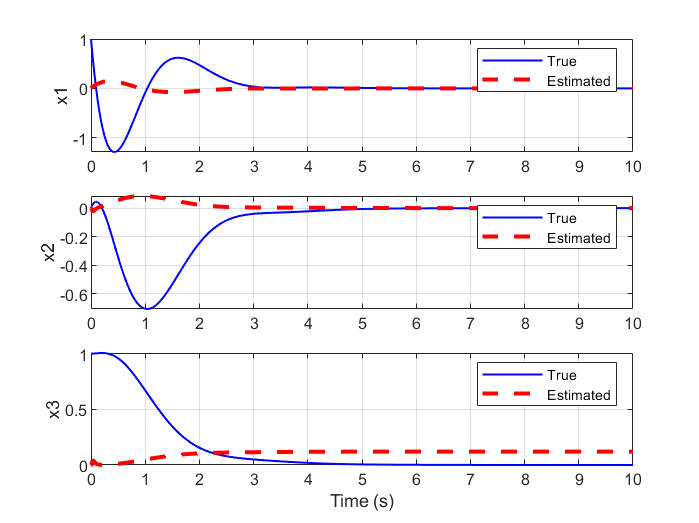


% Initial conditions
xn = [0; 0; 0];
tspan = 0:0.01:10;
ct = length(tspan);
z = zeros(2, ct);
y = zeros(1, ct);

% Simulate the system
for k = 2:ct
    y(k) = Cbar * xn(:, k-1);
    xn(:, k) = xn(:, k-1) + 0.01 * (Abar * xn(:, k-1) + Bbar);
    z(:, k) = z(:, k-1) + 0.01 * ((A22 - L * A12) * z(:, k-1) + ((A22 - L * A12) * L + A21) * y(k-1) + (B2 - L * B1));  
end

% Calculate the estimated state
x_hat = inv(P) * [1 0 0; L eye(2)] * [y; z];

% Simulate the true system
[t1, x] = ode45(@(t, x) system_dynamics(t, x, A, B), tspan, [1; 0; 1]);

figure;
subplot(3, 1, 1);
plot(t1, x(:, 1), "b-", 'linewidth', 1);
hold on;
plot(tspan, x_hat(1, :), "r--", 'linewidth', 2);
ylabel('x1');
legend('True', 'Estimated');
grid on;

subplot(3, 1, 2);
plot(t1, x(:, 2), "b-", 'linewidth', 1);
hold on;
plot(tspan, x_hat(2, :), "r--", 'linewidth', 2);
ylabel('x2');
legend('True', 'Estimated');
grid on;

subplot(3, 1, 3);
plot(t1, x(:, 3), "b-", 'linewidth', 1);
hold on;
plot(tspan, x_hat(3, :), "r--", 'linewidth', 2);
ylabel('x3');
legend('True', 'Estimated');
xlabel('Time (s)');
grid on;

**Question-14** : Design the closed-loop system by designing the feedback of the estimated modes in such a way that the poles of the closed-loop system are on the left side of the Jω axis and the stair response behaves in terms of leap and landing time. Plot the step response and system state variables. In fact, suppose that the system states are not available and the estimated states should be used for state feedback. In this question, consider the reviewer in the perfect order. (In fact, you'll need to design a mode feedback control system with a full-order router.)

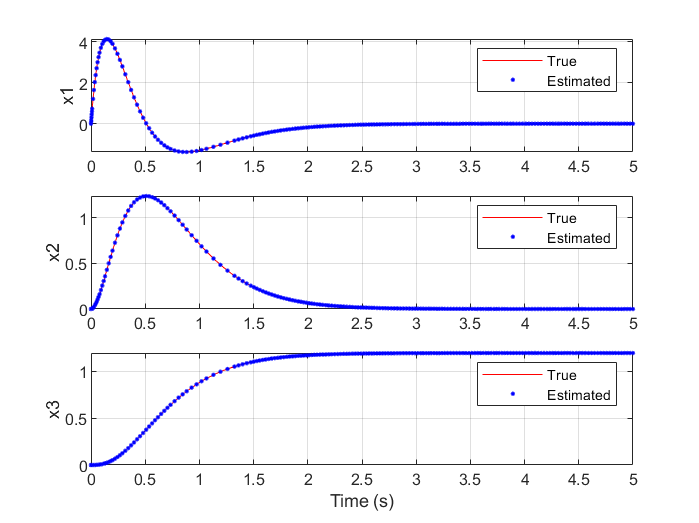

clear all;
clc;

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

tspan = [0 5];

% Simulate the system with observer and state feedback
[t, x] = ode45(@d_Q14, tspan, zeros(6,1));
X = x';

% Output response
y = C * X(4:6,:);

figure;
subplot(3,1,1);
plot(t, x(:,1), 'r-', t, x(:,4), 'b.');
ylabel('x1');
legend('True', 'Estimated');
grid on;

subplot(3,1,2);
plot(t, x(:,2), 'r-', t, x(:,5), 'b.');
ylabel('x2');
legend('True', 'Estimated');
grid on;

subplot(3,1,3);
plot(t, x(:,3), 'r-', t, x(:,6), 'b.');
ylabel('x3');
legend('True', 'Estimated');
xlabel('Time (s)');
grid on;

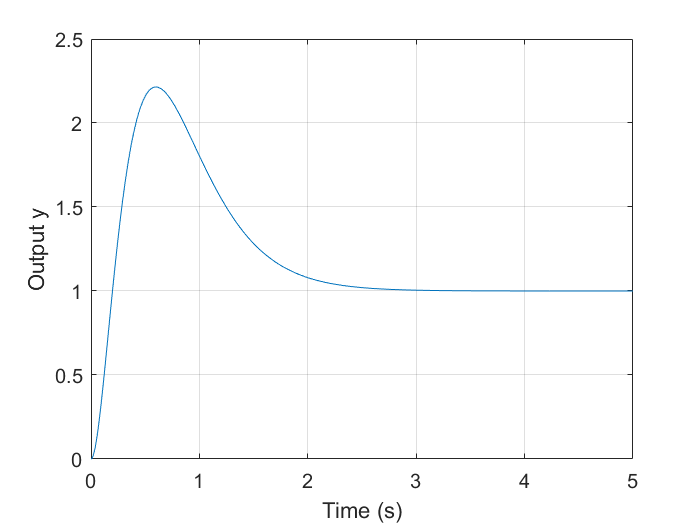


figure;
plot(t, y, '-');
ylabel('Output y');
xlabel('Time (s)');
grid on;

**Question-15** : For the hypothetical system, design a state feedback control system (regulator) with a reduced order observable.

clear all;
clc;

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs)

A =    -4.1705  -10.7750   -8.3050
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =          0    1.5000    0.8385


D = 0


P = [C; 1 0 0; 0 1 0];
inv_p = inv(P);
P1 = inv_p(1:3,1);
P2 = inv_p(1:3,2:3);
Abar = P * A * inv(P);
Bbar = P * B;

A22 = Abar(2:3, 2:3); 
A12 = Abar(1, 2:3);
A21 = Abar(2:3, 1);
A11 = Abar(1, 1);
B1 = Bbar(1, 1);
B2 = Bbar(2:3, 1);

% Desired poles for the controller and reduced-order observer
P_controller = [-5 -7 -10];
P_observer = [-7 -10];

% Calculate state feedback gain
K = place(A, B, P_controller)

K =    17.8295  144.2250  341.6950



% Calculate observer gain
k = place(A22', A12', P_observer);
L = k'

L =     4.4657
    7.3117


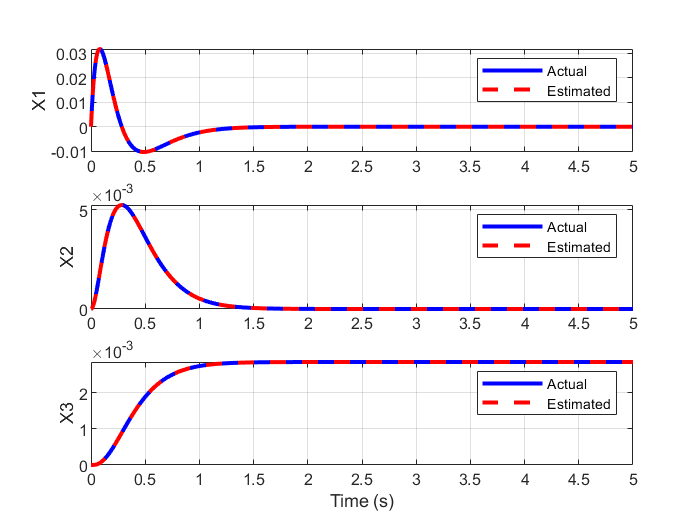


% Reduced-order observer parameters
B_l = B2 - L * B1;
AA = [A - B * K * P1 * C - B * K * P2 * L * C, -B * K * P2;
     ((A22 - L * A12) * L + (A21 - L * A11)) * C - B_l * K * P1 * C - B_l * K * P2 * L * C, (A22 - L * A12) - B_l * K * P2];
BB = [B; B_l];
CC = [C zeros(1, 2)];

% Time vector
t = linspace(0, 5, 1000);

% Simulate the closed-loop system
sys = ss(AA, BB, CC, 0);
[y,~,x] = lsim(sys, ones(1,1000), t);

% Extract true and estimated states
x_t = x(:,1:3);
z = x(:,4:5);
x_est = inv(P) * [y'; L * y' + z'];

% Plot the results
figure();
subplot(3,1,1);
plot(t, x_t(:,1), "b", t, x_est(1,:)', "r--", 'linewidth', 2);
legend("Actual", "Estimated");
ylabel("X1");
grid on;

subplot(3,1,2);
plot(t, x_t(:,2), "b", t, x_est(2,:)', "r--", 'linewidth', 2);
legend("Actual", "Estimated");
ylabel("X2");
grid on;

subplot(3,1,3);
plot(t, x_t(:,3), "b", t, x_est(3,:)', "r--", 'linewidth', 2);
legend("Actual", "Estimated");
ylabel("X3");
xlabel('Time (s)');
grid on;


disp('--------------------------------------------------------------------------------------')

--------------------------------------------------------------------------------------


**Question-16** :  For the given system, design a mode feedback control system with a full-order observable.

clear all;
clc;

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

% Desired pole locations for the controller and observer
controller_poles = [-7 -10 -12];
observer_poles = [-5 -7 -10];

% Calculate state feedback gain
K = place(A, B, controller_poles)

K =    24.8295  263.2250  831.6950



% Calculate observer gain
L = place(A', C', observer_poles)'

L =    23.6454
   41.0244
  -52.1253


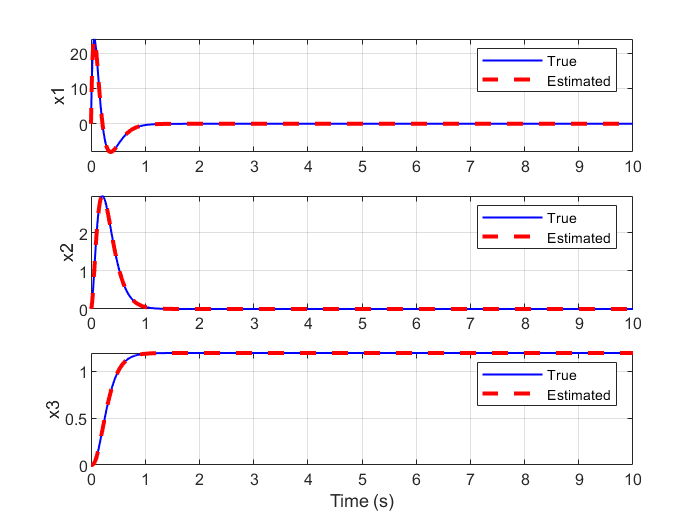

 
% Augmented matrices for the observer-based controller
Abar = [A - B * K, zeros(3); L * C, A - L * C - B * K];
Bbar = [B; B];
Cbar = [C, zeros(1, 3)];

% Calculate the feedforward gain
Ga = inv(C * inv(-A + B * K) * B);

% Create state-space system
sys = ss(Abar, Bbar, Cbar, 0);

% Time vector for simulation
t = linspace(0, 10, 1000);

% Simulate the system response
[y, ~, x] = lsim(sys, Ga * ones(1, 1000), t);

figure;
subplot(3,1,1);
plot(t, x(:,1), 'b-', 'linewidth', 1);
hold on;
plot(t, x(:,4), 'r--', 'linewidth', 2);
ylabel('x1');
legend('True', 'Estimated');
grid on;

subplot(3,1,2);
plot(t, x(:,2), 'b-', 'linewidth', 1);
hold on;
plot(t, x(:,5), 'r--', 'linewidth', 2);
ylabel('x2');
legend('True', 'Estimated');
grid on;

subplot(3,1,3);
plot(t, x(:,3), 'b-', 'linewidth', 1);
hold on;
plot(t, x(:,6), 'r--', 'linewidth', 2);
ylabel('x3');
legend('True', 'Estimated');
xlabel('Time (s)');
grid on;

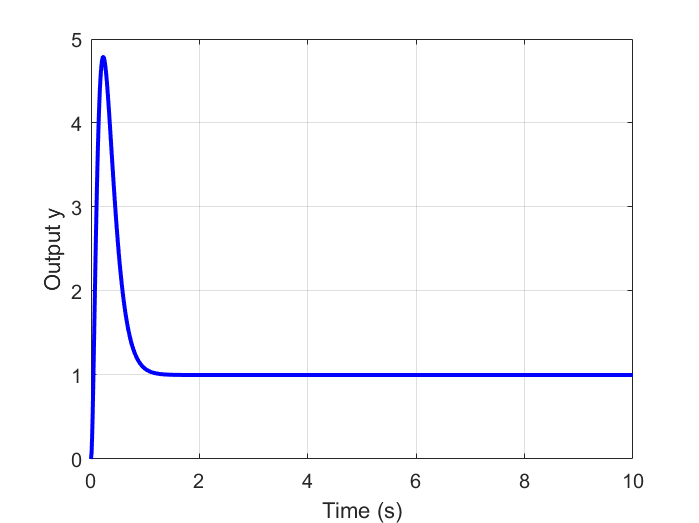


figure;
plot(t, y, 'b-', 'linewidth', 2);
ylabel('Output y');
xlabel('Time (s)');
grid on;

**Question-17**:  For the hypothetical system, design a mode feedback control system with a reduced order observable.

clear all;
clc;

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

P = [C; 1 0 0; 0 1 0];
inv_p = inv(P);
P1 = inv_p(1:3, 1);
P2 = inv_p(1:3, 2:3);
Abar = P * A / P;
Bbar = P * B;

A22 = Abar(2:3, 2:3); 
A12 = Abar(1, 2:3);
A21 = Abar(2:3, 1);
A11 = Abar(1, 1);
B1 = Bbar(1, 1);
B2 = Bbar(2:3, 1);


P_controller = [-5 -7 -10];
P_observer = [-12 -15];

% Calculate state feedback gain
K = place(A, B, P_controller);

% Calculate observer gain
k = place(A22', A12', P_observer)

k =     4.7544   18.7213


L = k'

L =     4.7544
   18.7213


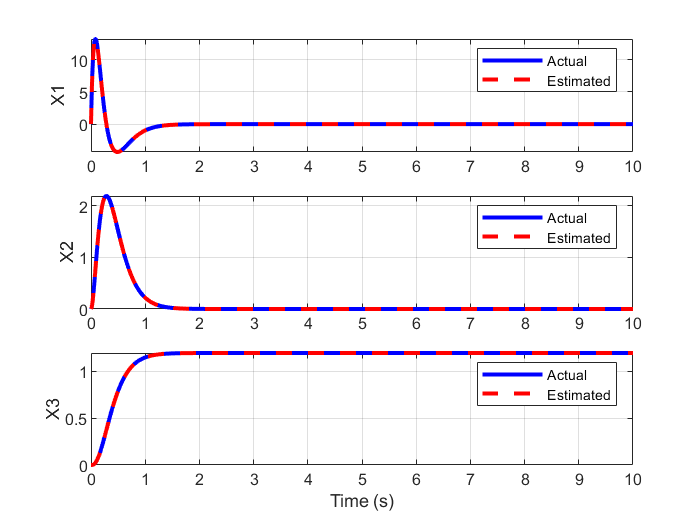


% Reduced-order observer parameters
B_l = B2 - L * B1;
AA = [A - B * K * P1 * C - B * K * P2 * L * C, -B * K * P2;
     ((A22 - L * A12) * L + (A21 - L * A11)) * C - B_l * K * P1 * C - B_l * K * P2 * L * C, (A22 - L * A12) - B_l * K * P2];
BB = [B; B_l];
CC = [C, zeros(1, 2)];

% Calculate the feedforward gain
Ga = inv(C * inv(-A + B * K) * B);
T = Ga * ones(1, 800);

% Create state-space system
sys = ss(AA, BB, CC, 0);

% Time vector for simulation
t = linspace(0, 10, 800);

% Simulate the system response
[y, ~, x_t] = lsim(sys, T, t);

% Extract true and estimated states
x = x_t(:, 1:3);
x_hat = x_t(:, 4:5);
x_est = inv(P) * [y'; L * y' + x_hat'];

% Plot the results
figure();
subplot(3,1,1);
plot(t, x(:,1), "b", t, x_est(1,:)', "r--", 'linewidth', 2);
legend("Actual", "Estimated");
ylabel("X1");
grid on;

subplot(3,1,2);
plot(t, x(:,2), "b", t, x_est(2,:)', "r--", 'linewidth', 2);
legend("Actual", "Estimated");
ylabel("X2");
grid on;

subplot(3,1,3);
plot(t, x(:,3), "b", t, x_est(3,:)', "r--", 'linewidth', 2);
legend("Actual", "Estimated");
ylabel("X3");
xlabel('Time (s)');
grid on;

**Question-18** : Gain the optimal state feedback gain of the system to minimize the following cost function for different values of the R matrix and the Q matrix.

Once assume the matrix Q to be constant and change the matrix R. Compare the simulation results. Once again, consider the matrix R to be fixed and change the matrix Q. Compare the simulation results.

clear all;
clc;

numerator_coeffs = [3 1.677];
denominator_coeffs = [2 8.341 21.55 16.61];
[A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);


t = linspace(0, 5, 1000);

% Case 1: Varying R with constant Q
Q = eye(3)

Q =      1     0     0
     0     1     0
     0     0     1


R_values = [1, 10, 100, 500]

R_values =      1    10   100   500


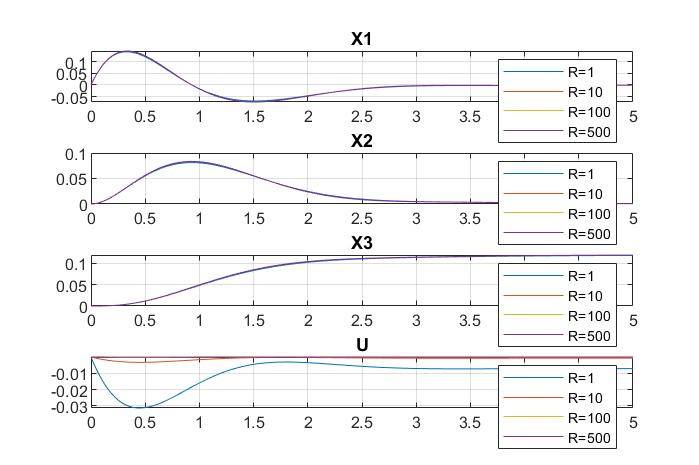


figure('Position', [100, 100, 1200, 800]);

for i = 1:length(R_values)
    R = R_values(i);
    [K,~,P] = lqr(A, B, Q, R);
    sys = ss(A-B*K, B, C, 0);
    [y,~,x] = lsim(sys, ones(1, 1000), t);
    u = -K * x';

    subplot(4,1,1);
    plot(t, x(:,1), 'DisplayName', ['R=' num2str(R)]);
    title('X1');
    hold on;

    subplot(4,1,2);
    plot(t, x(:,2), 'DisplayName', ['R=' num2str(R)]);
    title('X2');
    hold on;

    subplot(4,1,3);
    plot(t, x(:,3), 'DisplayName', ['R=' num2str(R)]);
    title('X3');
    hold on;

    subplot(4,1,4);
    plot(t, u, 'DisplayName', ['R=' num2str(R)]);
    title('U');
    hold on;
end

subplot(4,1,1);
legend();
grid on;

subplot(4,1,2);
legend();
grid on;

subplot(4,1,3);
legend();
grid on;

subplot(4,1,4);
legend();
grid on;

subplot(4,1,3)
xlim([0.00 5.00])
ylim([0.000 0.120])


% Case 2: Varying Q with constant R
R = 1

R = 1

Q_values = {eye(3), 10*eye(3), 100*eye(3), 500*eye(3)}

Q_values = 1×4 cell array
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}


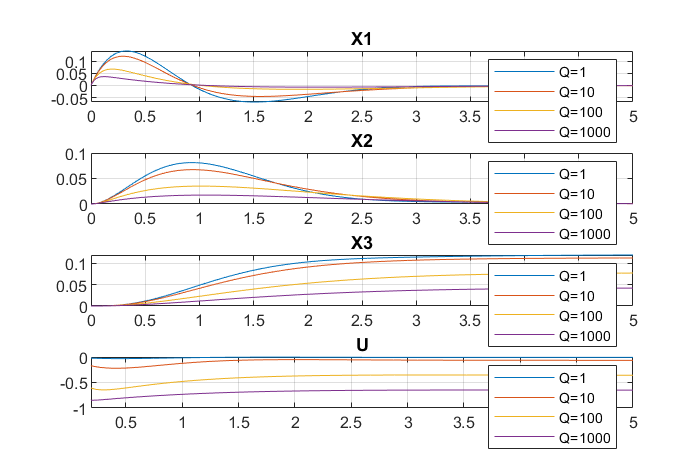


figure('Position', [100, 100, 1200, 800]);

for i = 1:length(Q_values)
    Q = Q_values{i};
    [K,~,P] = lqr(A, B, Q, R);
    sys = ss(A-B*K, B, C, 0);
    [y,~,x] = lsim(sys, ones(1, 1000), t);
    u = -K * x';

    subplot(4,1,1);
    plot(t, x(:,1), 'DisplayName', ['Q=' num2str(10^(i-1))]);
    title('X1');
    hold on;

    subplot(4,1,2);
    plot(t, x(:,2), 'DisplayName', ['Q=' num2str(10^(i-1))]);
    title('X2');
    hold on;

    subplot(4,1,3);
    plot(t, x(:,3), 'DisplayName', ['Q=' num2str(10^(i-1))]);
    title('X3');
    hold on;

    subplot(4,1,4);
    plot(t, u, 'DisplayName', ['Q=' num2str(10^(i-1))]);
    title('U');
    hold on;
end

subplot(4,1,1);
legend();
grid on;

subplot(4,1,2);
legend();
grid on;

subplot(4,1,3);
legend();
grid on;

subplot(4,1,4);
legend();
grid on;

subplot(4,1,4)
xlim([0.19 5.00])
ylim([-1.00 0.00])

### **Functions of all Questions:**

function dxdt = d_Q7(t, x, A, B, K)
    u = -K * x;
    dxdt = A * x + B * u;
end
%----------------------------------------------------------------
% Q -8 fcn:
function dxdt = d_Q8(t, x, A, B, C, K, p, r)
    u = -K * x + p * r;
    dxdt = A * x + B * u;
end
%-----------------------------------------------------------------
% Q -11 & 12 fcn:
function d_sys = observer_dynamics(~, x, A, B, C, L)
    n = size(A, 1);
    x_true = x(1:n);
    x_hat = x(n+1:end);
    u = 0;
    y = C * x_true;
    dx_true = A * x_true + B * u;
    dx_hat = A * x_hat + B * u + L * (y - C * x_hat);
    d_sys = [dx_true; dx_hat];
end
%--------------------------------------------------------------------
% Q -13 fcn:
function dx = system_dynamics(~, x, A, B)
    u = 0; 
    dx = A * x + B * u;
end
%--------------------------------------------------------------------
% Q -14 fcn:
function Z = d_Q14(t, x)
    numerator_coeffs = [3 1.677];
    denominator_coeffs = [2 8.341 21.55 16.61];
    [A, B, C, D] = tf2ss(numerator_coeffs, denominator_coeffs);

    P_observer = [-20 -25 -30];
    P_controller = [-3 -4 -5];

    % Calculate observer gain
    K_observer = acker(A', C', P_observer);
    L = K_observer';

    % Calculate state feedback gain
    K = acker(A, B, P_controller);

    r = 1;
    Ga = inv(C * inv(-A + B * K) * B);
    u = Ga * r;

    G = [A -B * K; L * C A - L * C - B * K];
    Z = G * x + [B; B] * u;
end